#### Compare the number of guesses people take to the number of guesses a bisection search algorith would take

% logical vector of whether person knows bisection search
class = logical([1, 1, 1, 0, 1, 0, 0, 0, 1, 1, 1, 0, 1, 0, 1, 1, 1, ...
    0, 0, 1, 0, 0, 0, 0, 0, 0, 1, 1, 0, 1]); % 1 if participant knew Bisection Search

people_nTurns = [12, 9, 12, 8, 3, 4, 12, 13, 8, 15, 11, 10, 16, 20, 10, ...
    9, 9, 7, 10, 13, 9, 11, 34, 8, 13, 9, 10, 6, 8, 12]';

[mean(people_nTurns), var(people_nTurns)]

ans =    11.0333   30.3782


[mean(machine_nTurns),  var(machine_nTurns)]

ans =     8.9667    2.6540


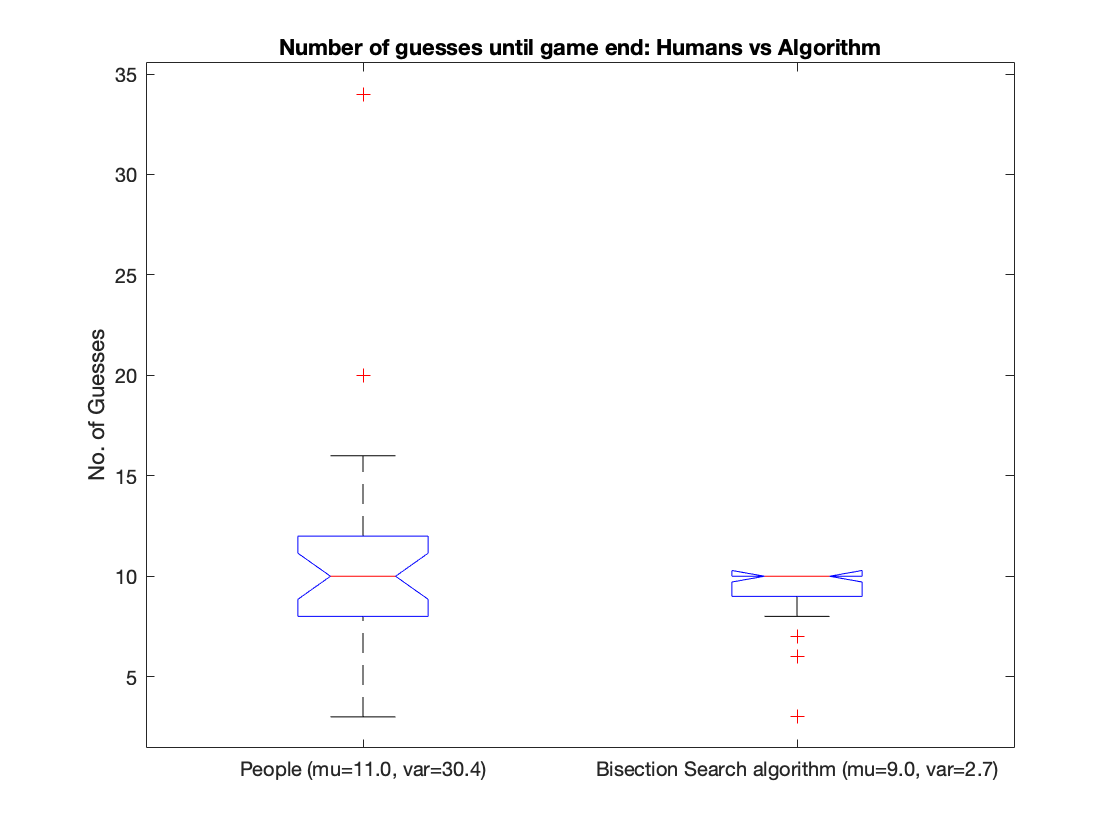


machine_nTurns = [10, 10, 9, 10, 3, 9, 9, 10, 10, 8, 10, 9, 9, 10, 10, ...
    8, 9, 10, 10, 10, 10, 7, 10, 10, 10, 10, 6, 8, 9, 6]'; 
% Bisection Search has worst-case complexity of O(logN). note that 10 ~= log(1000)

figure
boxplot([people_nTurns, machine_nTurns],'Notch','on','Labels', ...
    {'People (mu=11.0, var=30.4)', 'Bisection Search algorithm (mu=9.0, var=2.7)'})
ylabel('No. of Guesses')
title("Number of guesses until game end: Humans vs Algorithm")
hold off


% compare people who knew bisection search to those who did not
[mean(people_nTurns(class)), var(people_nTurns(class))]

ans =    10.3333   10.9524


[mean(people_nTurns(~class)),  var(people_nTurns(~class))]

ans =    11.7333   50.9238


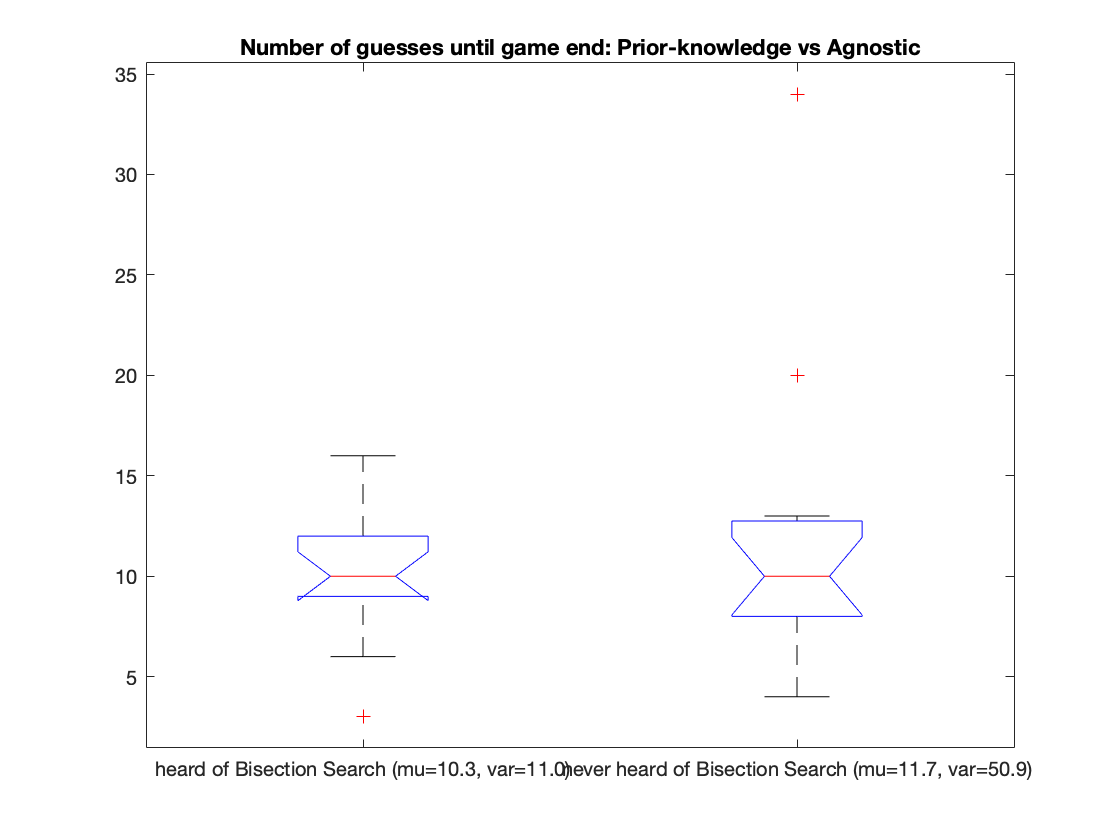


figure
boxplot([people_nTurns(class), people_nTurns(~class)],'Notch','on','Labels', ...
    {'heard of Bisection Search', 'never heard of Bisection Search'})
title("Number of guesses until game end: Prior-knowledge vs Agnostic")
hold off

#### Look at the absolute deviation of people from an EIG maximizing agent

% a cell array of the absolute errors from imformation maximizing bisection
% search at each guess
deltas = {[90, 45, 25, 49, 0, 0, 3, 2, 0, 1, 1, 0] ;
[0, 0, 0, 33, 0, 0, 1, 0, 0] ;
[0, 0, 0, 12, 0, 7, 5, 9, 8, 7, 2, 1] ;
[300, 300, 250, 0, 0, 2, 2, 0] ;
[0, 0, 0] ;
[431, 166, 36, 94] ;
[0, 150, 100, 50, 0, 0, 3, 2, 0, 2, 1, 1] ;
[478, 421, 25, 105, 70, 5, 40, 1, 4, 3, 3, 2, 2] ;
[0, 0, 25, 0, 5, 5, 0, 1] ;
[444, 450, 454, 132, 68, 84, 0, 0, 5, 5, 0, 5, 0, 0, 0] ;
[0, 0, 25, 25, 0, 0, 3, 3, 0, 0, 0] ;
[400, 450, 50, 150, 100, 0, 5, 5, 4, 1] ;
[0, 0, 0, 12, 0, 3, 0, 8, 6, 5, 4, 3, 22, 10, 4, 1] ;
[300, 300, 250, 200, 150, 100, 50, 0, 0, 3, 13, 9, 10, 11, 12, 13, 7, 3, 0, 1] ;
[0, 0, 0, 2, 5, 2, 3, 0, 0, 0] ;
[0, 0, 0, 22, 22, 22, 17, 12, 2] ;
[0, 150, 100, 50, 30, 16, 8, 0, 0] ;
[377, 338, 16, 5, 2, 1, 1] ;
[200, 100, 25, 25, 25, 0, 0, 3, 0, 1] ;
[455, 457, 382, 575, 175, 75, 0, 50, 6, 4, 1, 1, 1] ;
[0, 0, 25, 25, 0, 0, 1, 1, 1] ;
[266, 273, 23, 6, 11, 8, 12, 8, 1, 1, 0] ;
[261, 64, 77, 74, 69, 63, 100, 0, 5, 10, 10, 7, 12, 7, 6, 5, 4, 3, 378, 278, 178, 78, 28, 22, 3, 7, 5, 4, 3, 2, 1, 1, 0, 0] ;
[421, 39, 0, 0, 12, 0, 3, 1] ;
[0, 0, 25, 50, 0, 0, 10, 8, 0, 0, 2, 1, 1] ;
[0, 50, 50, 0, 15, 14, 13, 5, 0] ;
[0, 0, 0, 12, 2, 3, 1, 1, 0, 0] ;
[0, 100, 0, 12, 2, 2] ;
[29, 164, 114, 21, 1, 3, 2, 0] ;
[264, 118, 35, 47, 35, 25, 23, 0, 5, 5, 2, 4]};